% Adapted from Jean-Yves Tinevez (2024). Mean square displacement analysis of particles trajectories (https://github.com/tinevez/msdanalyzer), GitHub. Retrieved July 16, 2024.

[tracks, md] = importTrackMateTracks('B3_T0_full_Tracks.xml', true, false);
[tracks2, md2] = importTrackMateTracks('C1 T1_full_Tracks.xml', true, false);

plot3 = plotTracks(tracks2);

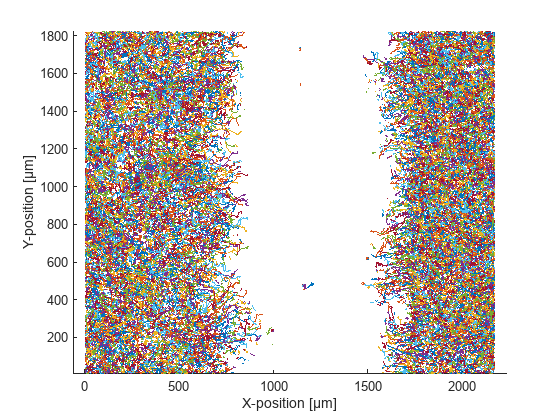

xlabel("X-position [" + md2.spaceUnits + "]")
ylabel("Y-position [" + md2.spaceUnits + "]")
axis equal
saveas(plot3, 'pdmsTracks.tif')
print(gcf,'pdmsTracks.png','-dpng','-r600'); 

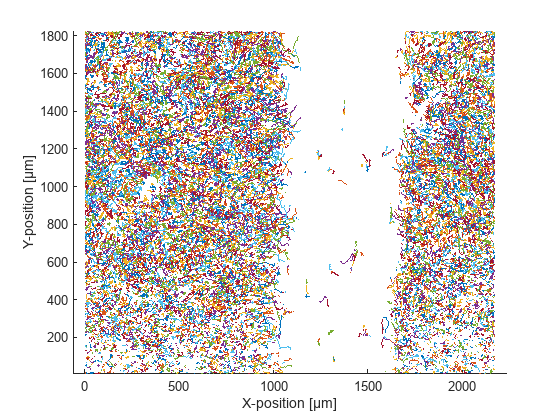

%subplot(2,2,1)
plot1 = plotTracks(tracks);
xlabel("X-position [" + md.spaceUnits + "]")
ylabel("Y-position [" + md.spaceUnits + "]") 
axis equal
print(gcf,'scratchTracks.png','-dpng','-r600');  
saveas(plot1, 'scratchTracks.tif')
hold off

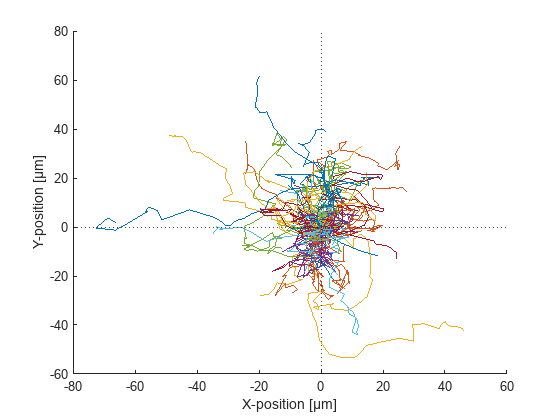

%subplot(2,2,2)
plot2 = plotAroundOrigin(tracks);
xlabel("X-position [" + md.spaceUnits + "]")
ylabel("Y-position [" + md.spaceUnits + "]")
print(gcf,'scratchTracksCentered.png','-dpng','-r600'); 
saveas(plot2, 'scratchTracksCentered.tif')
hold off

%subplot(2,2,3)
plot3 = plotTracks(tracks2);
xlabel("X-position [" + md2.spaceUnits + "]")
ylabel("Y-position [" + md2.spaceUnits + "]")
axis equal
saveas(plot3, 'pdmsTracks.tif')
print(gcf,'pdmsTracks.png','-dpng','-r600'); 
hold off

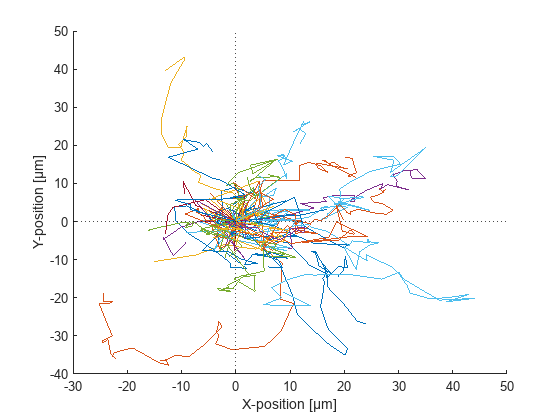

%subplot(2,2,4)
plot4 = plotAroundOrigin(tracks2);
xlabel("X-position [" + md2.spaceUnits + "]")
ylabel("Y-position [" + md2.spaceUnits + "]")
print(gcf,'pdmsTracksCentered.png','-dpng','-r600'); 
saveas(plot4, 'pdmsTracksCentered.tif')
hold off

function trackPlot = plotTracks(tracks)
    indices = 1:numel(tracks);
    n_tracks = numel(indices);
    for i = 1:n_tracks
        index = indices(i);
        track = tracks{index};
        %trackName = sprintf("Track %d", index);
    
        x = track(:,2);
        y = 1824.16 - track(:,3);
        if y<0
            track(:,3)
        end
    
        trackPlot = plot(x,y);
        hold on
        box off
    end
end

function originPlot = plotAroundOrigin(tracks)
    indices = 1:numel(tracks);
    n_tracks = numel(indices); % all tracks
    for i = floor(n_tracks/2):floor(n_tracks/2)+99
        index = indices(i);
        track = tracks{index};
        
        x1 = track(1,2);
        y1 = 1824.16-track(1,3);
        x = track(:,2)-x1;
        y = 1824.16-track(:,3)-y1;
    
        originPlot = plot(x,y);
        hold on
        box off
    end
    %ax = gca;
    %ax.XAxisLocation = 'origin';
    %ax.YAxisLocation = 'origin';
    yline(0,'k:')
    xline(0,'k:')
end